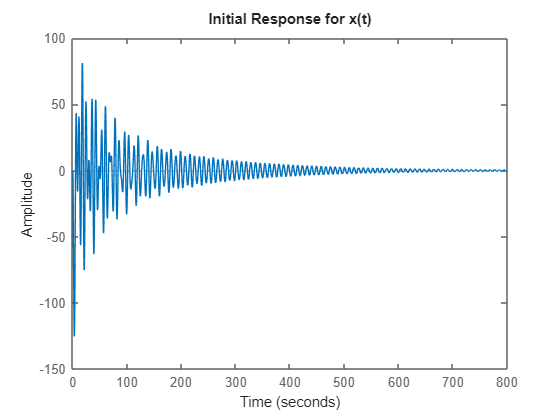

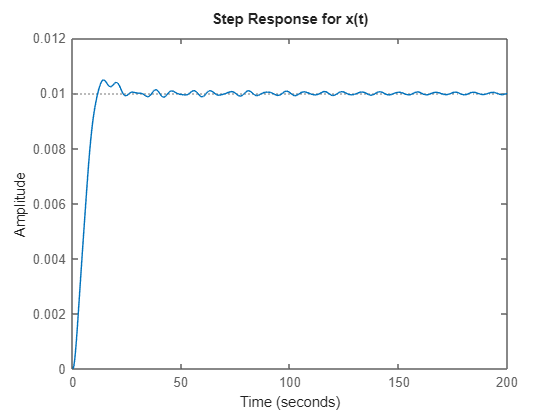

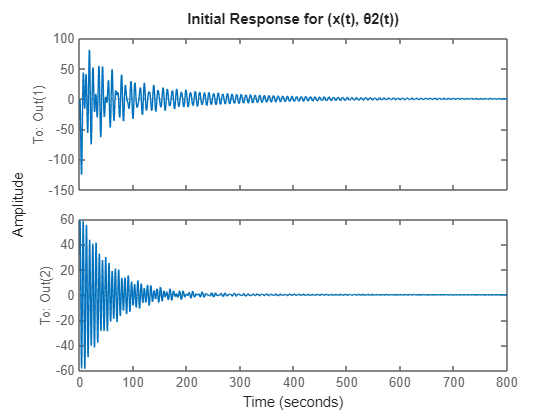

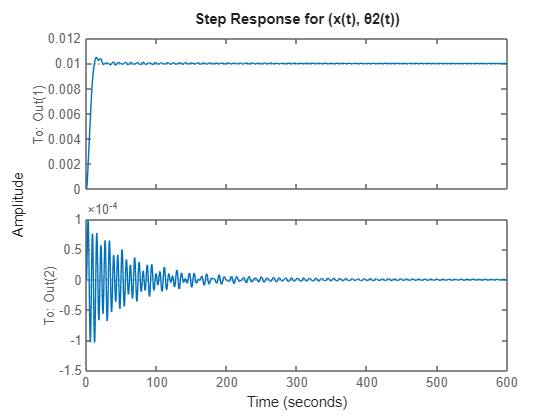

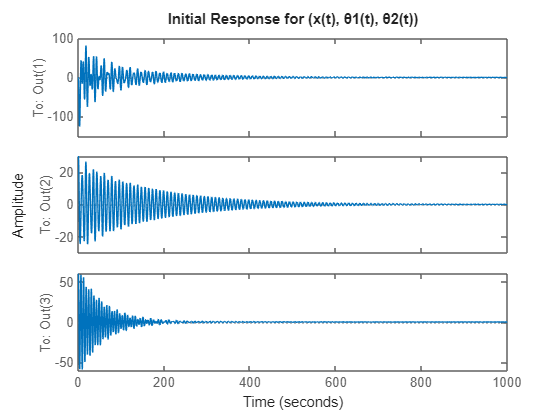

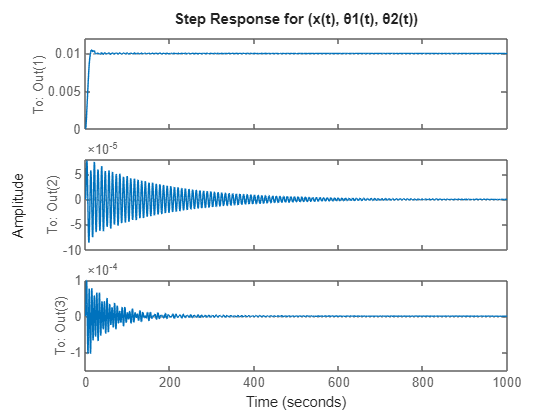

M = 1000;    % Mass of the cart
m1 = 100;    % Mass of pendulum 1
m2 = 100;    % Mass of pendulum 2
l1 = 20;     % Length of pendulum 1
l2 = 10;     % Length of pendulum 2
g = 9.81;    % Gravitational acceleration

A = [0 1 0 0 0 0;
     0 0 -(m1*g)/M 0 -(m2*g)/M 0;
     0 0 0 1 0 0;
     0 0 -(g*(M + m1))/(M*l1) 0 -(m2*g)/(M*l1) 0;
     0 0 0 0 0 1;
     0 0 -(m1*g)/(M*l2) 0 -(g*(M + m2))/(M*l2) 0];

B = [0; 1/M; 0; 1/(M*l1); 0; 1/(M*l2)];

% Output vector 
output_vectors = {
    [1 0 0 0 0 0], 'x(t)';                          % x(t)
    [1 0 0 0 0 0; 0 0 0 0 1 0], '(x(t), θ2(t))';    % (x(t), θ2(t))
    [1 0 0 0 0 0; 0 0 1 0 0 0; 0 0 0 0 1 0], '(x(t), θ1(t), θ2(t))' % (x(t), θ1(t), θ2(t))
};

D = 0;

Q = diag([100, 10, 100, 10, 1000, 100]); 
R = 0.01;  

% Initial conditions
x0 = [0; 0; 0.1; 0; 0.1; 0]; 
xhat0 = [0; 0; 0; 0; 0; 0]; % Observer estimate
x_combined0 = [x0; xhat0]; % Combined initial condition

poles = [-3;-5;-8;-9;-10;-12];

% LQR feedback gain
K = lqr(A, B, Q, R);

for idx = 1:size(output_vectors, 1)
    C = output_vectors{idx, 1};
    output_label = output_vectors{idx, 2};
    
    L = place(A', C', poles)'; % Luenberger gain
    A_c = [(A - B*K) B*K; zeros(size(A)) (A - L*C)];
    B_c = [B; zeros(size(B))];
    C_c = [C zeros(size(C))];

    sys = ss(A_c, B_c, C_c, D);

    % initial response
    figure('Name', ['Initial Response for ', output_label]);
    initial(sys, x_combined0);
    title(['Initial Response for ', output_label]);

    %step response
    figure('Name', ['Step Response for ', output_label]);
    step(sys);
    title(['Step Response for ', output_label]);
end

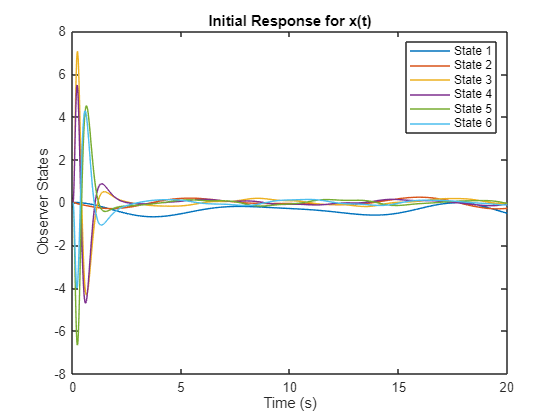

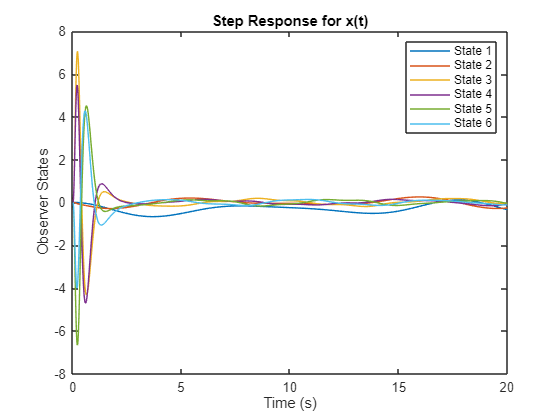

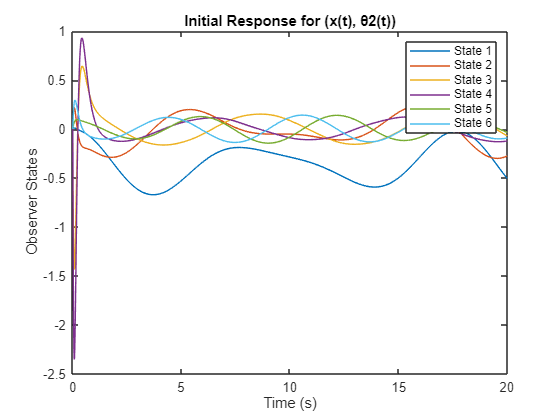

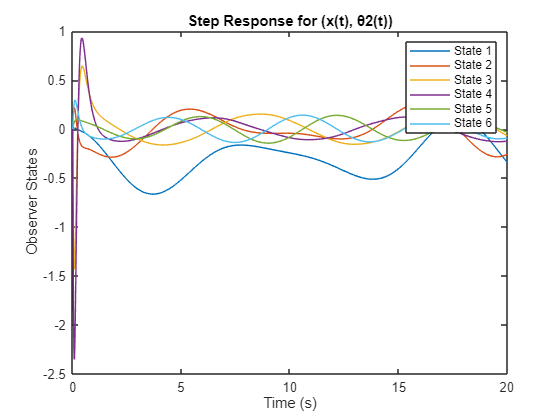

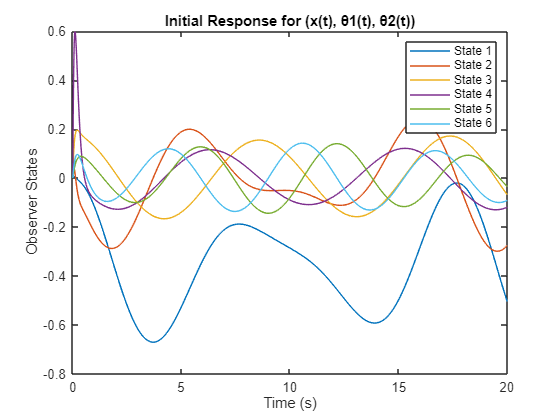

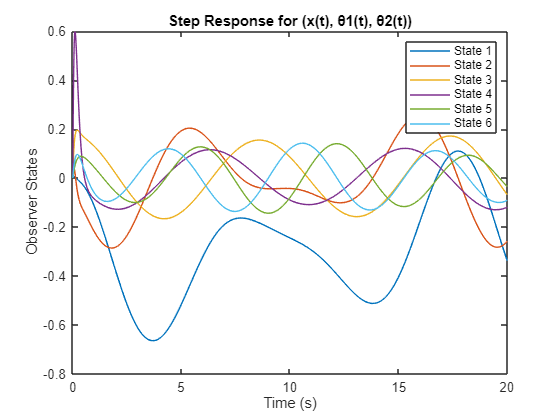

M = 1000;    % Mass of the cart
m1 = 100;    % Mass of pendulum 1
m2 = 100;    % Mass of pendulum 2
l1 = 20;     % Length of pendulum 1
l2 = 10;     % Length of pendulum 2
g = 9.81;    % Gravitational acceleration


A = [0 1 0 0 0 0;
     0 0 -(m1*g)/M 0 -(m2*g)/M 0;
     0 0 0 1 0 0;
     0 0 -(g*(M + m1))/(M*l1) 0 -(m2*g)/(M*l1) 0;
     0 0 0 0 0 1;
     0 0 -(m1*g)/(M*l2) 0 -(g*(M + m2))/(M*l2) 0];

B = [0; 1/M; 0; 1/(M*l1); 0; 1/(M*l2)];

% Output vectors
output_vectors = {
    [1 0 0 0 0 0], 'x(t)';                          % x(t)
    [1 0 0 0 0 0; 0 0 0 0 1 0], '(x(t), θ2(t))';    % (x(t), θ2(t))
    [1 0 0 0 0 0; 0 0 1 0 0 0; 0 0 0 0 1 0], '(x(t), θ1(t), θ2(t))' % (x(t), θ1(t), θ2(t))
};

% LQR feedback gain
Q = diag([100, 10, 100, 10, 1000, 100]); 
R = 0.01;                               
K = lqr(A, B, Q, R);

nonlinear_dynamics = @(t, X, F) [
    X(2);
    (F - m1*l1*X(4)^2*sin(X(3)) - m2*l2*X(6)^2*sin(X(5)) ...
    - m1*g*cos(X(3))*sin(X(3)) - m2*g*cos(X(5))*sin(X(5))) / ...
    (M + m1 + m2 - m1*cos(X(3))^2 - m2*cos(X(5))^2);
    X(4);
    ((F - m1*l1*X(4)^2*sin(X(3)) - m2*l2*X(6)^2*sin(X(5)) ...
    - m1*g*cos(X(3))*sin(X(3)) - m2*g*cos(X(5))*sin(X(5))) * cos(X(3)) ...
    - (M + m1 + m2 - m1*cos(X(3))^2 - m2*cos(X(5))^2) * g * sin(X(3))) / ...
    (l1 * (M + m1 + m2 - m1*cos(X(3))^2 - m2*cos(X(5))^2));
    X(6);
    ((F - m1*l1*X(4)^2*sin(X(3)) - m2*l2*X(6)^2*sin(X(5)) ...
    - m1*g*cos(X(3))*sin(X(3)) - m2*g*cos(X(5))*sin(X(5))) * cos(X(5)) ...
    - (M + m1 + m2 - m1*cos(X(3))^2 - m2*cos(X(5))^2) * g * sin(X(5))) / ...
    (l2 * (M + m1 + m2 - m1*cos(X(3))^2 - m2*cos(X(5))^2))
];


for idx = 1:size(output_vectors, 1)
    C = output_vectors{idx, 1};       
    output_label = output_vectors{idx, 2}; 
    
  
    poles = [-3; -5; -8; -9; -10; -12];
    L = place(A', C', poles)';
    
    nonlinear_observer_dynamics = @(t, X_combined, F) [
        % Nonlinear system dynamics
        nonlinear_dynamics(t, X_combined(1:6), F);
        % Observer dynamics
        A*X_combined(7:12) + B*F + ...
        L * (C * X_combined(1:6) - C * X_combined(7:12))
    ];

    % Initial conditions for nonlinear system 
    x0 = [0; 0; deg2rad(10); 0; deg2rad(5); 0];
    xhat0 = [0; 0; 0; 0; 0; 0];                
    x_combined0 = [x0; xhat0];                 

    t_span = [0 20];

    % Initial response
    [t_initial, X_initial] = ode45(@(t, X) nonlinear_observer_dynamics(t, X, 0), t_span, x_combined0);

    % Step response
    step_input = @(t) 1 * (t >= 0); % Unit step input
    [t_step, X_step] = ode45(@(t, X) nonlinear_observer_dynamics(t, X, step_input(t)), t_span, x_combined0);

    observer_initial = X_initial(:, 7:12);
    observer_step = X_step(:, 7:12);

    % initial response
    figure('Name', ['Initial Response for ', output_label]);
    plot(t_initial, observer_initial);
    xlabel('Time (s)');
    ylabel('Observer States');
    title(['Initial Response for ', output_label]);
    legend(arrayfun(@(i) sprintf('State %d', i), 1:size(observer_initial, 2), 'UniformOutput', false));

    % step response
    figure('Name', ['Step Response for ', output_label]);
    plot(t_step, observer_step);
    xlabel('Time (s)');
    ylabel('Observer States');
    title(['Step Response for ', output_label]);
    legend(arrayfun(@(i) sprintf('State %d', i), 1:size(observer_step, 2), 'UniformOutput', false));
end